plotDevice01 = [];
plotDevice02 = [];
problemCounter = 0;
while 1
    problemCounter = problemCounter + 1;
    c = input("Please Enter Vector c in row form: ");
    A = input("Please Enter Matrix A: ");
    b = input("Please Enter Vector b in column form: ");
    t1=tic;
    temp01 = size(A);
    m = temp01(1,1);
    n = temp01(1,2);
    mL1 = m;
    nL1 = n + m;
    AL1 = [A eye(m)];
    bL1 = b;
    cL1 = sum([A zeros(m) b]);
    JBL1 = [nL1-mL1+1 : nL1];
    JNL1 = [1 : nL1-mL1];
    SimplexTableL1 = [cL1 ;AL1 bL1];
    disp("Problem " +problemCounter);
    disp("First Table Of L1 Problem In Matrix Form: ");
    disp(SimplexTableL1);
    xL1 = [zeros(nL1-mL1,1); SimplexTableL1(2:end,end)];
    zL1 =  SimplexTableL1(1,end);
    [SimplexTableL1,JBL1,JNL1,zL1,xL1,Detector] = SimplexMethod(SimplexTableL1,JBL1,JNL1,mL1,nL1,xL1,zL1);
    if zL1 == 0
        ArtificialZeroes =[];
        for i = 1:m
            if JBL1(i) >= n + 1
               ArtificialZeroes = [ArtificialZeroes i];
            end
        end
        if isequal(ArtificialZeroes,[])
            JB = JBL1;
            JN = [];
            for i = JNL1
                if i <= n
                    JN = [JN i];
                end
            end
            temp02 = [-c zeros(1,m) 0];
            for i = 1:n
                for j = 1:m
                    if i == JB(j)
                        temp02 = temp02 + c(i)*SimplexTableL1(j,:);
                    end
                end
            end
            SimplexTable = [temp02(1,1:n) temp02(1,end); SimplexTableL1(2:end,1:n) SimplexTableL1(2:end,end)];
            x = [zeros(n-m,1); SimplexTable(2:end,end)];
            for i = JN
                x(i) = 0;
            end
            j=2;
            for i = JB
                x(i) = SimplexTable(j,end);
                j = j + 1;
            end
            z = SimplexTable(1,end);
            disp("First Table Of L2 Problem In Matrix Form: ")
            disp(SimplexTable)
            [SimplexTable,JB,JN,z,x,Detector] = SimplexMethod(SimplexTable,JB,JN,m,n,x,z);
            if Detector == 1
                disp ("The Problem Is Unbounded");
                CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
            else
                disp(" The Answer Is :")
                disp(x)
                disp("And " + z + " Is The Optimal Value!")
                CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
            end
        else
            RedundantConstraint = [];
            for i = ArtificialZeroes(1,:)
                if isequal(SimplexTableL1(i,1:JBL1(i)-1),zeros(1,JBL1(i)-1))
                    RedundantConstraint = [RedundantConstraint JBL1(i)-n];
                end
            end
            if isequal(RedundantConstraint,[])
                [SimplexTableL1,JBL1,JNL1] = BaseSwaper(SimplexTableL1,JBL1,JNL1,mL1,nL1,ArtificialZeroes);
                JB = JBL1;
                JN = [];
                for i = JNL1
                    if i <= n
                        JN = [JN i];
                    end
                end
                for i = 1:n
                    for j = 1:m
                        if i == JB(j)
                            temp02 = temp02 + c(i)*SimplexTableL1(j,:);
                        end
                    end
                end
                SimplexTable = [temp02(1,1:n) temp02(1,end); SimplexTableL1(2:end,1:n) SimplexTableL1(2:end,end)];
                x = [zeros(n-m,1); SimplexTable(2:end,end)];
                for i = JN
                    x(i) = 0;
                end
                j=2;
                for i = JB
                    x(i) = SimplexTable(j,end);
                    j = j + 1;
                end
                z = SimplexTable(1,end);
                disp("First Table Of L2 Problem In Matrix Form: ")
                disp(SimplexTable)
                [SimplexTable,JB,JNL1,z,x,Detector] = SimplexMethod(SimplexTable,JB,JN,m,n,x,z);
                if Detector == 1
                    disp ("The Problem Is Unbounded");
                    CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
                else
                    disp(" The Answer Is :")
                    disp(x)
                    disp("And " + z + " Is The Optimal Value!")
                    CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
                end
            else
                disp("The Following Constraints Are Redundent: ");
                disp(RedundantConstraint);
                CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
            end
        end
    else
        disp("The Problem Is Not Feasable!");
        CountinuationCheck = input("Do You Wish To Solve Another Problem? (Typye y for Yes And n for No): ",'s');
    end
    t2=toc(t1);
    plotDevice01 = [plotDevice01; n t2];
    plotDevice02 = [plotDevice02; m t2];
    if CountinuationCheck == "n"
        break
    end
end

Problem 1


First Table Of L1 Problem In Matrix Form: 


     0     2     1     1     1     0     0     0     6
     0     1     1     0     0     1     0     0     2
     1     0     0     1     0     0     1     0     2
    -1     1     0     0     1     0     0     1     2



First Table Of L2 Problem In Matrix Form: 


     0     1     0     0     0     0
     0     1     1     0     0     2
     1     0     0     1     0     2
    -1     0    -1     0     1     0



 The Answer Is :


     0
     2
     0
     2
     0



And -2 Is The Optimal Value!


Problem 2


First Table Of L1 Problem In Matrix Form: 


   -0.6667    1.5000   -1.0000   -1.0000   -1.0000         0         0         0    5.1667
    0.3333    0.5000   -1.0000         0         0    1.0000         0         0    0.1667
    2.0000   -2.0000         0   -1.0000         0         0    1.0000         0    2.0000
   -3.0000    3.0000         0         0   -1.0000         0         0    1.0000    3.0000



The Problem Is Not Feasable!


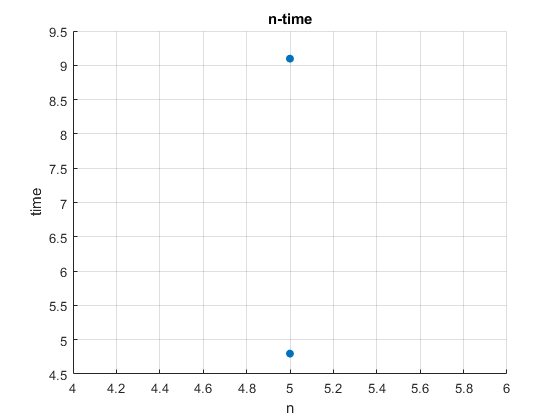

rateInRegardsToN = [0 diff((plotDevice01(:,2))')./diff((plotDevice01(:,1))')];
rateInRegardsToM = [0 diff((plotDevice02(:,2))')./diff((plotDevice02(:,1))')];
TitlesN = ["n" "Time" "rate"];
TitlesM = ["m" "Time" "rate"];
finalTableN = [TitlesN; plotDevice01 rateInRegardsToN'];
finalTableM = [TitlesM; plotDevice02 rateInRegardsToM'];
scatter((plotDevice01(:,1))',(plotDevice01(:,2))','filled')
grid on
xlabel('n')
ylabel('time')
title('n-time')

disp(finalTableN)

    "n"    "Time"      "rate"
    "5"    "9.0967"    "0"   
    "5"    "4.7972"    "-Inf"



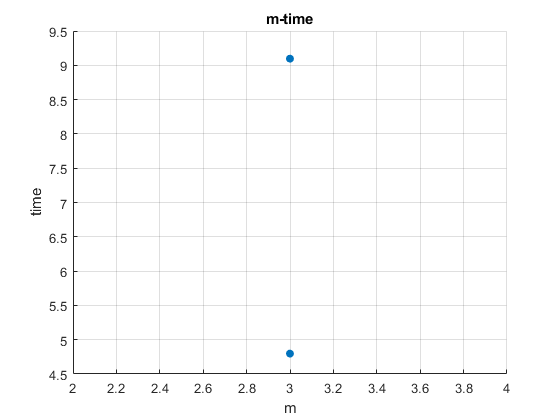

scatter((plotDevice02(:,1))',(plotDevice02(:,2))','filled')
grid on
xlabel('m')
ylabel('time')
title('m-time')

disp(finalTableM)

    "m"    "Time"      "rate"
    "3"    "9.0967"    "0"   
    "3"    "4.7972"    "-Inf"



function [NewSimplexTable,NewJB,NewJN,NewZ,NewX,Detector] = SimplexMethod(SimplexTable,JB,JN,m,n,x,z)
    while 1
        if SimplexTable(1,1:end-1)<=0
            NewSimplexTable=SimplexTable;
            NewJB=JB;
            NewJN=JN;
            NewZ=z;
            NewX=x;
            Detector=0;
            break
        end
        [maX,r] = max(SimplexTable(1,1:n));
        if SimplexTable(2:end,r) <= zeros(m,1)
            NewSimplexTable=SimplexTable;
            NewJB=JB;
            NewJN=JN;
            NewZ=z;
            NewX=x;
            Detector=1;
            break
        end
        MinDeductionTest = [];
        for i = 2:m+1
            if SimplexTable(i,r) > 0
                MinDeductionTest = [MinDeductionTest; i (SimplexTable(i,end)/SimplexTable(i,r))];
            end
        end
        [teta,temp02] = min(MinDeductionTest(:,2));
        s = MinDeductionTest(temp02,1);
        for i = 1:n-m
            if JN(i) == r
                JN(i) = JB(s-1);
            end 
        end
        JB(s-1) = r;
        SimplexTable(s,:) = (SimplexTable(s,r)^(-1))*SimplexTable(s,:);
        for i = 1 : m+1
            if i ~= s
                SimplexTable(i,:) = SimplexTable(i,:) - SimplexTable(i,r)*SimplexTable(s,:);
            end
        end
        for i = JN
            x(i) = 0;
        end
        j=2;
        for i = JB
            x(i) = SimplexTable(j,end);
            j = j + 1;
        end
        z = SimplexTable(1,end);
    end
end

function [NewSimplexTable,NewJB,NewJN] = BaseSwaper(SimplexTable,JB,JN,m,n,ArtificialZeroes)
    for i = ArtificialZeroes
        for j = SimplexTable(i,1:JB(i)-1)
            if j ~= 0
                r = JB(i);
                s = i;
                break 
            end
        end
        for k = 1:n-m
            if JN(k) == r
                JN(k) = JB(s-1);
            end 
        end
        JB(s-1) = r;
        SimplexTable(s,:) = (SimplexTable(s,r)^(-1))*SimplexTable(s,:);
        for k = 1 : m+1
            if k ~= s
                SimplexTable(k,:) = SimplexTable(k,:) - SimplexTable(k,r)*SimplexTable(s,:);
            end
        end
    end
    NewSimplexTable=SimplexTable;
    NewJB=JB; 
    NewJN=JN;
end
